syms d15 d22 d31 d33 tx ty tz real;

N = @(a)[a.*a ...
    a(:,[3 1 2]) .* a(:,[2 3 1]); ...
    a([3 1 2],:) .* a([2 3 1],:) .* 2 ...
    a([3 1 2],[3 1 2]) .* a([2 3 1],[2 3 1]) + a([3 1 2],[2 3 1]) .* a([2 3 1],[3 1 2])];

d = [0 0 0 0 d15 -2*d22;-d22 d22 0 d15 0 0;d31 d31 d33 0 0 0]

$$d = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & d_{15} & -2\,d_{22}\\ -d_{22} & d_{22} & 0 & d_{15} & 0 & 0\\ d_{31} & d_{31} & d_{33} & 0 & 0 & 0 \end{array}\right)$$


Ax = [1 0 0; 0 cos(tx) sin(tx); 0 -sin(tx) cos(tx)];
Ay = [cos(ty) 0 sin(ty); 0 1 0; -sin(ty) 0 cos(ty)];
Az = [cos(tz) sin(tz) 0; -sin(tz) cos(tz) 0; 0 0 1];

dp = Ax*d*N(Ax).';

dp21 = expand(dp(2,1))

$$dp21 = d_{31}\,\sin\left(\mathrm{tx}\right)-d_{22}\,\cos\left(\mathrm{tx}\right)$$

dp22 = expand(dp(2,2))

$$dp22 = d_{33}\,{\sin\left(\mathrm{tx}\right)}^{3}+d_{22}\,{\cos\left(\mathrm{tx}\right)}^{3}+d_{15}\,{\cos\left(\mathrm{tx}\right)}^{2}\,\sin\left(\mathrm{tx}\right)+d_{31}\,{\cos\left(\mathrm{tx}\right)}^{2}\,\sin\left(\mathrm{tx}\right)$$

dp23 = expand(dp(2,3))

$$dp23 = d_{31}\,{\sin\left(\mathrm{tx}\right)}^{3}-d_{15}\,{\cos\left(\mathrm{tx}\right)}^{2}\,\sin\left(\mathrm{tx}\right)+d_{22}\,\cos\left(\mathrm{tx}\right)\,{\sin\left(\mathrm{tx}\right)}^{2}+d_{33}\,{\cos\left(\mathrm{tx}\right)}^{2}\,\sin\left(\mathrm{tx}\right)$$

dp24 = expand(dp(2,4))

$$dp24 = d_{15}\,{\cos\left(\mathrm{tx}\right)}^{3}-d_{15}\,\cos\left(\mathrm{tx}\right)\,{\sin\left(\mathrm{tx}\right)}^{2}-2\,d_{22}\,{\cos\left(\mathrm{tx}\right)}^{2}\,\sin\left(\mathrm{tx}\right)-2\,d_{31}\,\cos\left(\mathrm{tx}\right)\,{\sin\left(\mathrm{tx}\right)}^{2}+2\,d_{33}\,\cos\left(\mathrm{tx}\right)\,{\sin\left(\mathrm{tx}\right)}^{2}$$

dp25 = expand(dp(2,5))

$$dp25 = 0$$

dp26 = expand(dp(2,6))

$$dp26 = 0$$

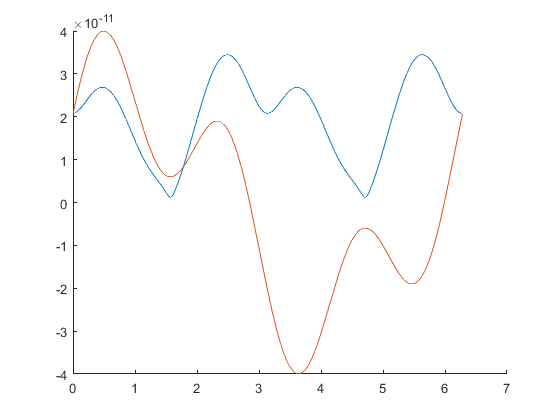


d = subs(d, d15, sym('69.2e-12'));
d = subs(d, d22, sym('20.8e-12'));
d = subs(d, d31, sym('-0.85e-12'));
d = subs(d, d33, sym('6e-12'));

dp = Ax*d*N(Ax).';

hold on
dparr = sqrt(dp(2,1)^2 + dp(2,3)^2);
fplot(dparr, [0 2*pi])
fplot(dp(2,2), [0 2*pi])
hold off